load BOHnet
Inputs;
Targets;
I;
x = transpose (I);



y = BOHnet(x);
ty = transpose(y);
plotregression(targets, ty)
e = gsubtract(targets,y);
totalPerformance = perform(BOHnet,targets,ty)

totalPerformance = 59.5659

totalRMSE = sqrt(totalPerformance)

totalRMSE = 7.7179

**Variable: Noble Metals**

inputNM = Inputs;

inputNM.Au = zeros([318 1]); inputNM.Pd = zeros([318 1]);
inputNM = double(inputNM{:,:});

inputNM = fillmissing(inputNM, "constant", 0);
transposedInputNM = transpose(inputNM);

xNM = transposedInputNM;

yNM = BOHnet(xNM);
tyNM = transpose(yNM);
%e = gsubtract(t,yNM);
performance = perform(BOHnet,targets,tyNM)

performance = 1.1828e+03

totalRMSENM = sqrt(performance)

totalRMSENM = 34.3924

RImpNM = (totalRMSENM - totalRMSE)

RImpNM = 25.5137

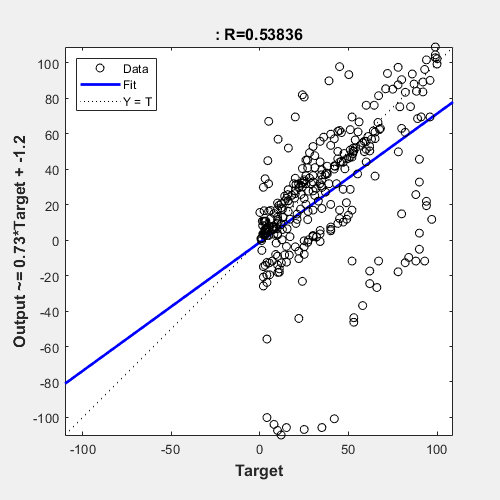


plotregression(targets, tyNM)

**Variable : Promoters**

inputPr = Inputs;

inputPr.Sm = double(inputPr.Sm);
inputPr.Ca = double(inputPr.Ca);
inputPr.Ba = double(inputPr.Ba);
inputPr.Mg = double(inputPr.Mg);

inputPr.Zr = zeros([318 1]); inputPr.Bi = zeros([318 1]);C3N4 = zeros([318 1]); inputPr.Mn = zeros([318 1]);
inputPr.V = zeros([318 1]); inputPr.Co = zeros([318 1]); inputPr.Cu = zeros([318 1]); inputPr.Al = zeros([318 1]);
inputPr.Sm = zeros([318 1]); inputPr.Ba = zeros([318 1]); inputPr.Ca = zeros([318 1]); inputPr.Mg = zeros([318 1]);
inputPr = double(inputPr{:,:});
inputPr = fillmissing(inputPr, "constant", 0);

transposedInputPr = transpose(inputPr);

xPr = transposedInputPr;

yPr = BOHnet(xPr);
tyPr = transpose(yPr);
%e = gsubtract(t,yPr);
performance = perform(BOHnet,targets,tyPr)

performance = 225.6516

totalRMSEPr = sqrt(performance)

totalRMSEPr = 15.0217

RImpPr = (totalRMSEPr - totalRMSE)

RImpPr = 6.1430

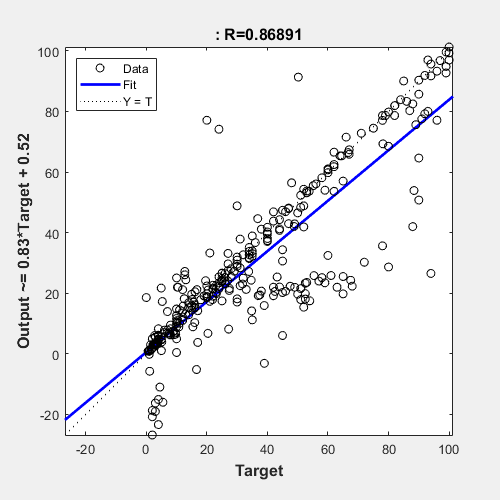

plotregression(targets, tyPr)

**Variable: CeO2 Type**

inputCT = Inputs;
inputCT.DCeO2Type1 = zeros([318 1]) ; inputCT.DCeO2Type2 = zeros([318 1]); inputCT.DCeO2Type3 = zeros([318 1]); inputCT.DCeO2Type4 = zeros([318 1]); inputCT.DCeO2Type5 = zeros([318 1]); inputCT.DCeO2Type6 = zeros([318 1]); inputCT.DCeO2Type7 = zeros([318 1]); inputCT.DCeO2Type8 = zeros([318 1]); inputCT.DCeO2Type9 = zeros([318 1]); inputCT.DCeO2Type10 = zeros([318 1]) ;

inputCT;
inputCT = double(inputCT{:,:});

inputCT = fillmissing(inputCT, "constant", 0);
transposedInputCT = transpose(inputCT);

xCT = transposedInputCT;


yCT = BOHnet(xCT);
tyCT = transpose(yCT);
%e = gsubtract(t,yCT);
performance = perform(BOHnet,targets,tyCT);
totalRMSECT = sqrt(performance);
RImpCT = (totalRMSECT - totalRMSE)

RImpCT = 12.5106

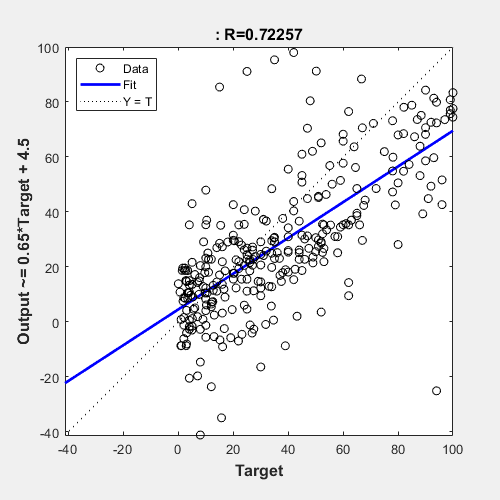

plotregression(targets, tyCT)

**Variable: Solvents**

inputSv = Inputs;
inputSv.DSolvent1 = zeros([318 1]); inputSv.DSolvent2 = zeros([318 1]); inputSv.DSolvent3 = zeros([318 1]); inputSv.DSolvent4 = zeros([318 1]);
inputSv.DSolvent5 = zeros([318 1]); inputSv.DSolvent6 = zeros([318 1]); inputSv.DSolvent7 = zeros([318 1]); inputSv.DSolvent8 = zeros([318 1]);
inputSv.DSolvent9 = zeros([318 1]); inputSv.DSolvent10 = zeros([318 1]);

inputSv = double(inputSv{:,:});

inputSv = fillmissing(inputSv, "constant", 0);
transposedInputSv = transpose(inputSv);
xSv = transposedInputSv;


ySv = BOHnet(xSv);
tySv = transpose(ySv);
%e = gsubtract(t,ySv);
performance = perform(net,targets,tySv)

performance = 383.4265

totalRMSESv = sqrt(performance)

totalRMSESv = 19.5813

RImpSv = (totalRMSESv - totalRMSE)

RImpSv = 10.7026

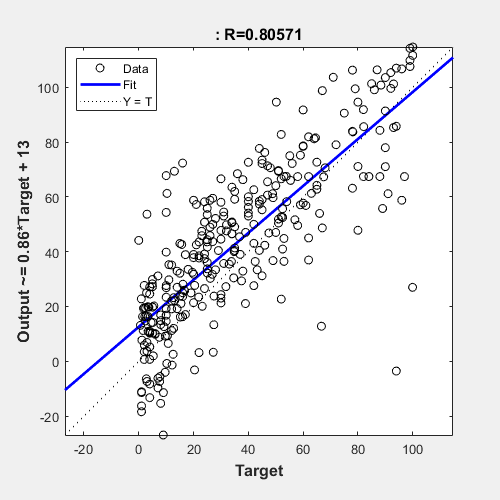

plotregression(targets, tySv)

**Variable: Volume of Solution**

inputSA = Inputs;
inputSA.SolutionAmount = zeros([318 1]) ;  

inputSA;
inputSA = double(inputSA{:,:});

inputSA = fillmissing(inputSA, "constant", 0);
transposedInputSA = transpose(inputSA);

xSA = transposedInputSA;


ySA = BOHnet(xSA);
tySA = transpose(ySA);
%e = gsubtract(t,ySA);
performance = perform(BOHnet,targets,tySA)

performance = 145.3434

totalRMSESA = sqrt(performance)

totalRMSESA = 12.0558

RImpSA = (totalRMSESA-totalRMSE)

RImpSA = 3.1772

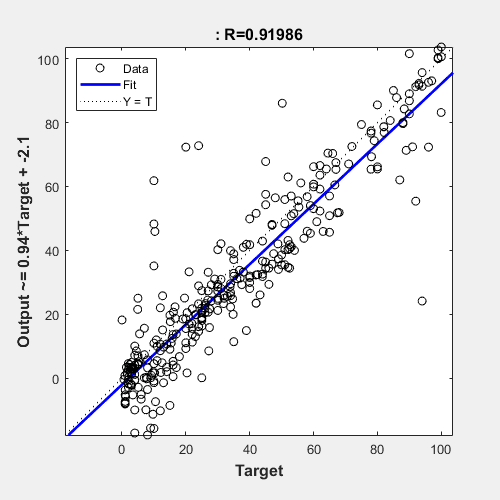

plotregression(targets, tySA)

**Variable: Concentration of Benzyl Alcohol**

inputCB = Inputs;
inputCB.ConcBOHmol = zeros([318 1]); 
inputCB = double(inputCB{:,:});

inputCB = fillmissing(inputCB, "constant", 0);
transposedInputCB = transpose(inputCB);
xCB = transposedInputCB;


yCB = BOHnet(xCB);
tyCB = transpose(yCB);
%e = gsubtract(t,ySv);
performance = perform(net,targets,tyCB)

performance = 316.0091

totalRMSECB = sqrt(performance)

totalRMSECB = 17.7766

RImpCB = (totalRMSECB - totalRMSE)

RImpCB = 8.8980

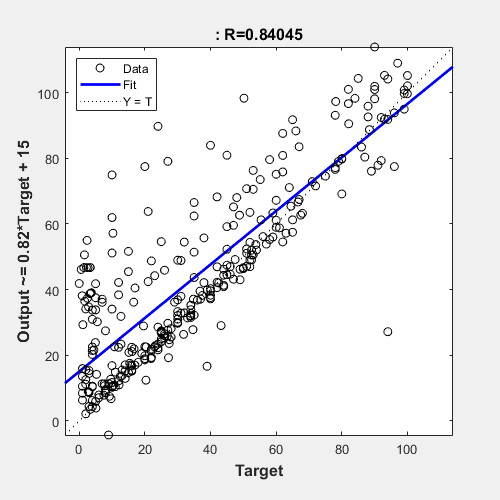

plotregression(targets, tyCB)

**Variable: Reaction Time**

inputRt = Inputs;
inputRt.ReactionTimeh = zeros([318 1]); 
inputRt = double(inputRt{:,:});

inputRt = fillmissing(inputRt, "constant", 0);
transposedInputRt = transpose(inputRt);
xRt = transposedInputRt;


yRt = BOHnet(xRt);
tyRt = transpose(yRt);
%e = gsubtract(t,yRt);
performance = perform(net,targets,tyRt)

performance = 1.0611e+03

totalRMSERt = sqrt(performance)

totalRMSERt = 32.5745

RImpRt = (totalRMSERt - totalRMSE)

RImpRt = 23.6958

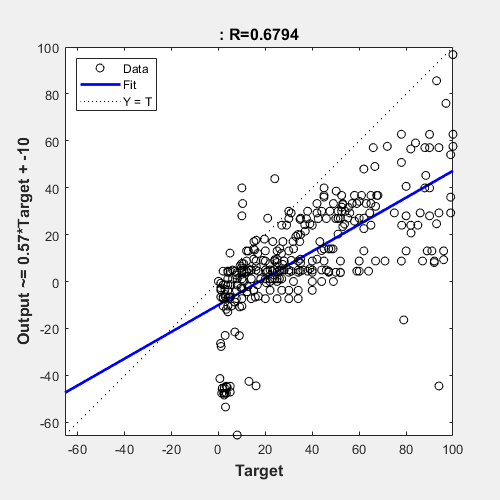

plotregression(targets, tyRt)

**Variable: Catalyst Amount**

inputCA = Inputs;
inputCA.CatalystAmountg = zeros([318 1]) ;  

inputCA;
inputCA = double(inputCA{:,:});

inputCA = fillmissing(inputCA, "constant", 0);
transposedInputCA = transpose(inputCA);

xCA = transposedInputCA;


yCA = BOHnet(xCA);
tyCA = transpose(yCA);
%e = gsubtract(t,yCA);
performance = perform(BOHnet,targets,tyCA)

performance = 402.8180

totalRMSECA = sqrt(performance)

totalRMSECA = 20.0703

RImpCA = (totalRMSECA-totalRMSE)

RImpCA = 11.1917

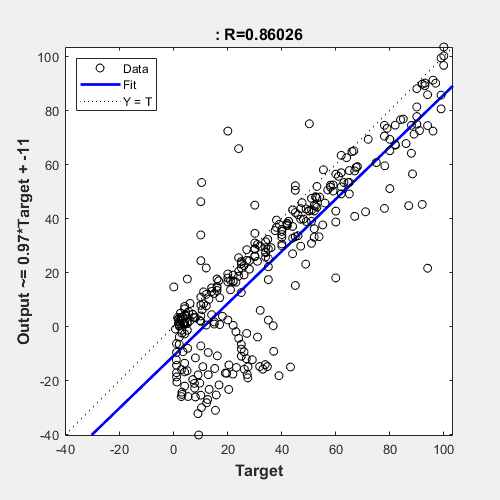

plotregression(targets, tyCA)

**Variable: Reaction Temperature**

inputRT = Inputs;
inputRT.TemperatureK = zeros([318 1]); 
inputRT = double(inputRT{:,:});

inputRT = fillmissing(inputRT, "constant", 0);
transposedInputRT = transpose(inputRT);
xRT = transposedInputRT;


yRT = BOHnet(xRT);
tyRT = transpose(yRT);
%e = gsubtract(t,ySv);
performance = perform(net,targets,tyRT)

performance = 3.9489e+03

totalRMSERT = sqrt(performance)

totalRMSERT = 62.8406

RImpRT = (totalRMSERT - totalRMSE)

RImpRT = 53.9620

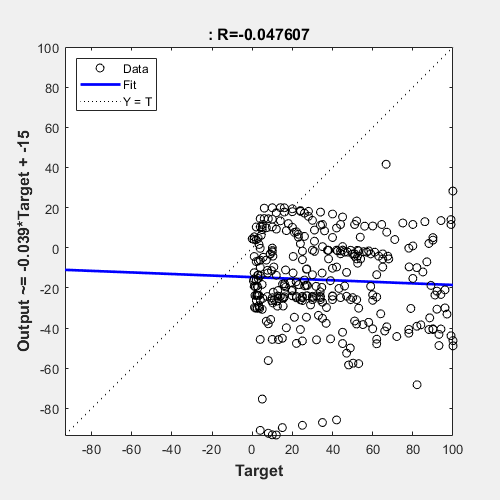

plotregression(targets, tyRT)